**Klasszikus ortogonális polinomok**

**Laguerre polinom**


$$[0; \infty], \quad w(x) = e^{-x},\\
P_0(x) = 1, \quad P_1(x) = x-1,\\
P_{n+1}(x) = (x-(2n+1)) \cdot P_n(x) -
n^2 \cdot  P_{n-1}(x) \quad (n = 1, 2, . . .).$$



$$n=1:\\
P_2(x) = (x-3) \cdot H_1(x) - 1\cdot  H_0(x) = (x-3)(x-1)-1=x^2-4x+2
$$



$$P_3(x) =(x-5) \cdot P_2(x) -4\cdot  P_1(x) = 
(x-5)(x^2-4x+2)-4\cdot (x-1) =\\
= x^3-9x^2-18x-6$$


N=5;
P=zeros(N+1,N+1);
Pef=zeros(N+1,N+1);
P(1,N+1)=1;
P(2,N:N+1)=[1,-1];
for k=2:N
P(k+1,1:N+1)=[P(k,2:N+1),0]...
    -(2*k-1)*[P(k,1:N+1)]-(k-1)^2*P(k-1,1:N+1);
end
P

P =      0     0     0     0     0     1
     0     0     0     0     1    -1
     0     0     0     1    -4     2
     0     0     1    -9    18    -6
     0     1   -16    72   -96    24
     1   -25   200  -600   600  -120


% P a rekurzió miatt mindig egy főegyütthatős
Pef=P;

% for k=0:N
% Pef(k+1,:)=P(k+1,:)/P(k+1,N-k+1);
% end
% Pef

Rajzoljuk ki az egy főegyütthatós Laguerre polinomokat!

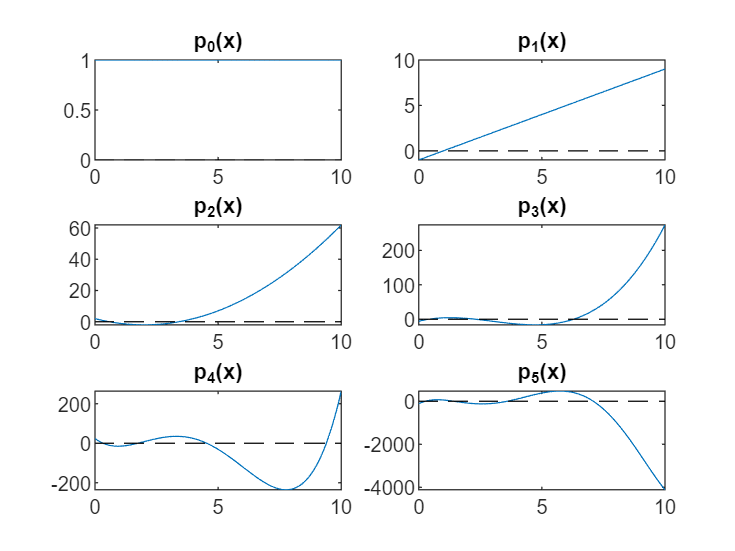

a=10;
xx=linspace(0,a,100);

for k=1:6
    subplot(3,2,k)
    pk=Pef(k,:);
    ppk=polyval(pk,xx);
    plot(xx,ppk,'-',xx,0*xx,'k--');
    title(sprintf('p_%d(x)',k-1));
end